# Prognostic Health Management

**Name**: 

Kwak, Jin/21900031

Kim, Sunwoo/22000090

**Date**       :2024.10.05

**Modified**:2024.10.12

# Introduction

In this lab, [](https://www.kamp-ai.kr/aidataDetail?AI_SEARCH=&page=1&DATASET_SEQ=23&EQUIP_SEL=&GUBUN_SEL=C004025&FILE_TYPE_SEL=&WDATE_SEL=CLICK_NUM)[AI dataset for early detection of equipment abnormalities](https://www.kamp-ai.kr/aidataDetail?AI_SEARCH=&page=1&DATASET_SEQ=23&EQUIP_SEL=&GUBUN_SEL=C004025&FILE_TYPE_SEL=&WDATE_SEL=CLICK_NUM) is used to develop a machine learning model for coil defect diagnosis(Hot-Air Process Equipment)

### **Process Description**

Hot-Air Drying Process:

    - Ensures that the film and protective agents adhere stably to the metal surface after plating

    - Completely dries moisture from the product surface.

    - Used in various fields(e.g. electronic component coating, automotive paint processes, and ceramic processes)

    - **Process Defects**

        - High power consumption using coil $\rightarrow$Overheating, Irregular temperature transmission $\rightarrow$Poor product quality/Equipment Fault

        - Coil fault may cause issues with the cooling motor $\rightarrow$ Vibration patterns changes.

The goal is to identify these changes to diagnose the issues early on and prevent equipment failure.

## Goal of the Project

Two separate, distinguishable goals.

- Development of a Machine Learning model for coil defect diagnosis using data in Hot-Air process equipment

- Analysis of the Remaining Useful Life trend and establish degradation model

## Specific Goals

1.1) Achieve detection(Normal/Error) accuracy up to 90% 

1.2) Ensure the model performance with Feature Reduction and analyze the feature reduction

2.1) 80% < Probability of Predicted RUL within αbound after Train-Test Breakpoint

## Dataset

Dataset name: [AI dataset for early detection of equipment abnormalities](https://www.kamp-ai.kr/aidataDetail?AI_SEARCH=&page=1&DATASET_SEQ=23&EQUIP_SEL=&GUBUN_SEL=C004025&FILE_TYPE_SEL=&WDATE_SEL=CLICK_NUM)

Data Measurement:

- PLC data(Sampling Period: 5[sec])

- Sound data

Data Categories:

- Numerical data from PLC 

- Sound data:

- Error Lot list

## **Goal of the Project**

Two main goals of the project are introduced in this project. The dataset is originally used for classification. Authors will prepare for a **ML model for fault classification** and **Fault Diagnosis Model(Remaining Useful Life Estimation Model)**

- Development of a Machine Learning model for coil defect diagnosis using data in Hot-Air process equipment

- Analysis of the Remaining Useful Life trend and establish **degradation model**

## **Expected Outcome**

**Before: **Difficulty on immediate problem check of coil defects on-site on real-time base

**After: **Quickly respond to equipment fault $\rightarrow$Equipment management, Increase in productivity.

## Schedule

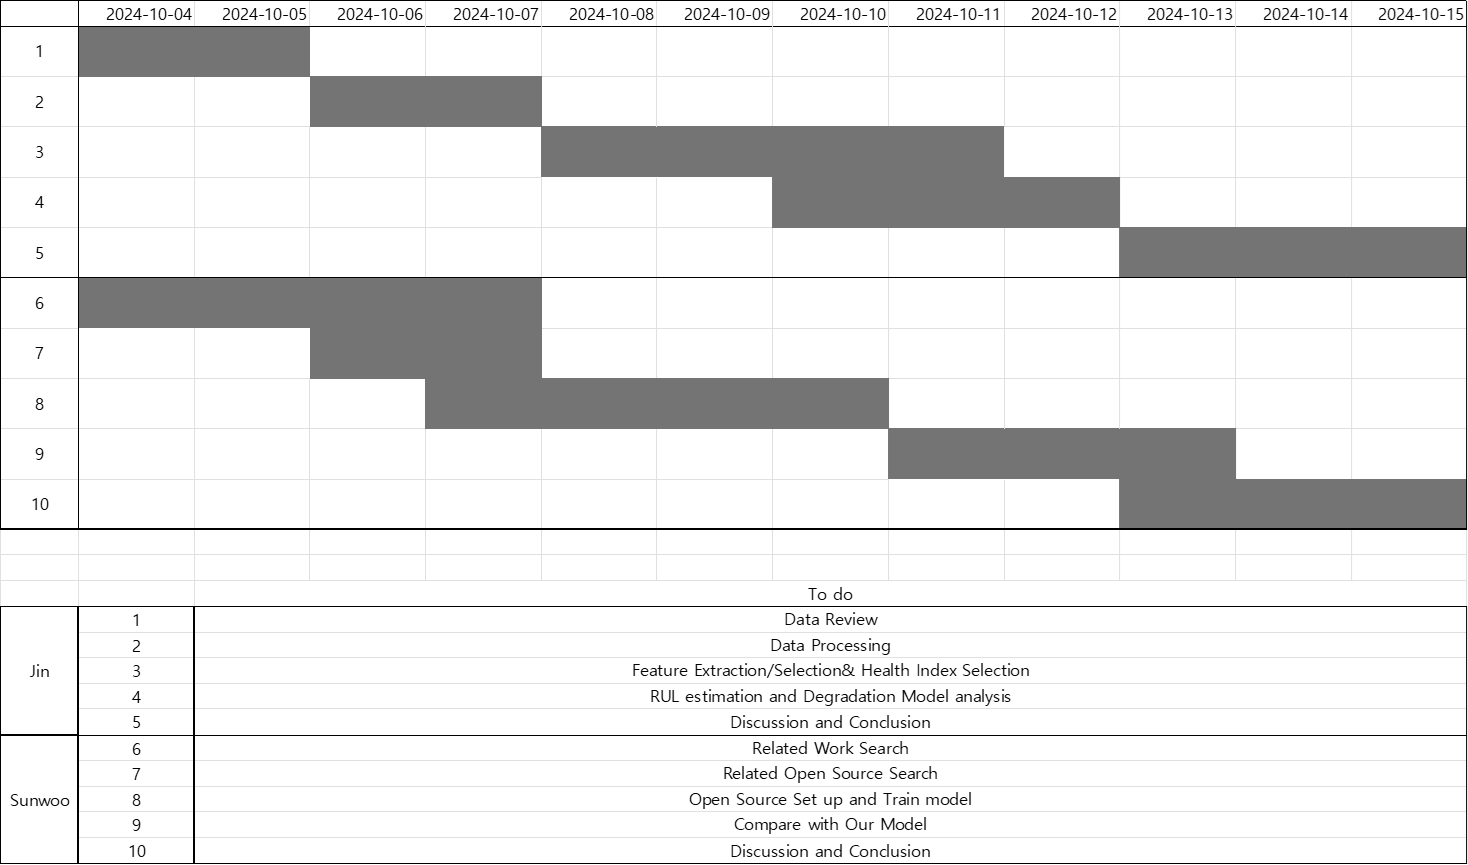

clc; clear all;
addpath("data\FAN_sound_error\");
addpath("data\FAN_sound_OK\")   ;D
addpath("data\5공정_180sec\")   ;

**Import Sound Data **

N_sound_error = 13                               ;
N_sound_normal= 170                              ;
error_sound_filename  = "FAN_sound_error_0%d.wav";
normal_sound_filename = "FAN_sound_0%d.wav"      ;
for idx = 1:9
    filename = sprintf(error_sound_filename,idx) ;
    [y,Fs] = audioread(filename)                 ;
    sound_error{idx,1} = y                       ;
    sound_error{idx,2} = Fs                      ;
    filename = sprintf(normal_sound_filename,idx);
    [y,Fs] = audioread(filename)                 ;
    sound_normal{idx,1} = y                      ;
    sound_normal{idx,2} = Fs                     ;
end
error_sound_filename = "FAN_sound_error_%d.wav"  ;
normal_sound_filename= "FAN_sound_%d.wav"        ;
for idx = 10:13
    filename = sprintf(error_sound_filename,idx) ;
    [y,Fs] = audioread(filename)                 ;
    sound_error{idx,1} = y                       ;
    sound_error{idx,2} = Fs                      ;
end
for idx = 10:N_sound_normal
    filename = sprintf(normal_sound_filename,idx);
    [y,Fs] = audioread(filename)                 ;
    sound_normal{idx,1} = y                      ;
    sound_normal{idx,2} = Fs                     ;
end

**Import PLC data**

Unfortunately, the time-series data is not strictly real-time, in which means that this data is collected every 5 seconds approximately.

day   = [6:10,13:17,23,24,27:30,1,5:8,12:15,18:22,25:27];
month = [9*ones(1,16),10*ones(1,17)];
dates = datetime(2021,month,day,'Format','uuuu.MM.dd');
txt_form = "kemp-abh-sensor-%s.csv";
for idx = 1:length(day)
    file_name    = sprintf(txt_form,dates(idx));
    data_temp    = readmatrix(file_name) ; 
    plc_data{idx}= data_temp(:,[1,2,4,5]); 
end


**Data Enumeration**

Cell data will be in time-series and each features are grouped by a struct.

% Enumerations
IDX      = 1  ;
PROCESS  = 2  ;
TEMP     = 3  ;
CURRENT  = 4  ;
% For cell data
RAW_DATA = 1  ;
MAX_FREQ = 2  ;
FEAT     = 3  ;


**The sound data** is very similar to the vibration data as it has amplitude and frequency. Time and frequency features are to be extracted for the data analysis.

However, the sound data is subdivided into normal/error which means this should be only used as classification not RUL. Only possible if the sound data can be collected on real-time

for idx = 1 : N_sound_error
    sound_error{idx,3} = get_features(sound_error{idx,1});
end
for idx = 1 : N_sound_normal
    sound_normal{idx,3} = get_features(sound_normal{idx,1});
end

Compare time-domain sound data of normal/error

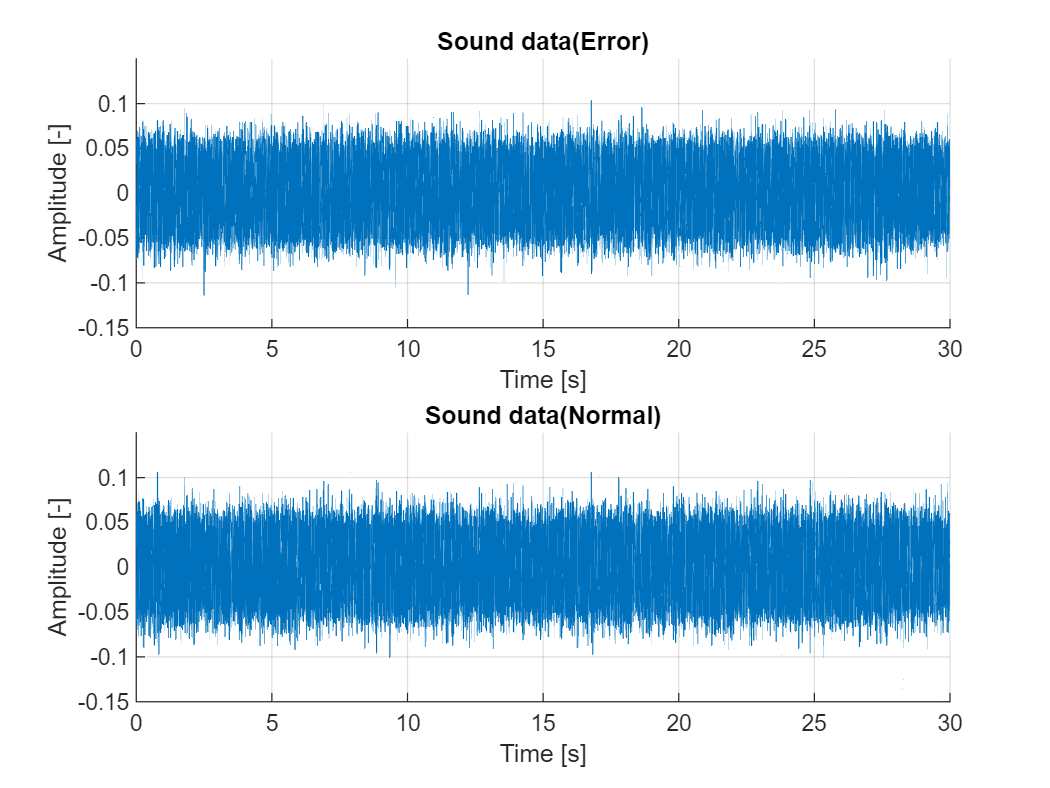

idx = 13;

ex_sound_error = sound_error {idx,RAW_DATA}(:,1);
ex_sound_normal= sound_normal{idx,RAW_DATA}(:,1);
time = 0:1/sound_error{idx,MAX_FREQ}:(length(ex_sound_error)-1)/Fs;

figure;
subplot(2,1,1); hold on;
title('Sound data(Error)','FontWeight','bold');
plot(time, ex_sound_error);grid on;
xlabel('Time [s]'); ylabel("Amplitude [-]");
time = 0:1/sound_normal{idx,MAX_FREQ}:(length(ex_sound_normal)-1)/Fs;
ylim([-0.15 0.15]);
subplot(2,1,2); hold on;
title('Sound data(Normal)','FontWeight','bold');
plot(time, ex_sound_normal); grid on;
xlabel('Time [s]'); ylabel("Amplitude [-]");
ylim([-0.15 0.15]);

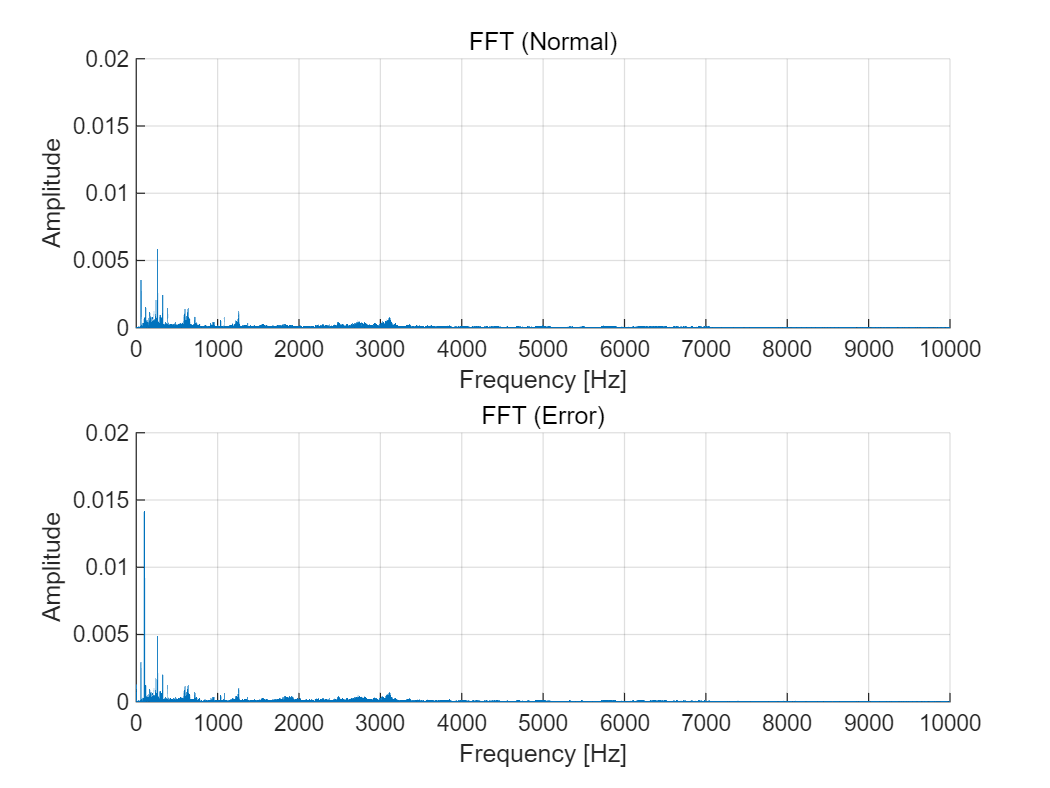

Fs = 44100;  %Hz
figure;
[freq, amp_normal] = get_fft(ex_sound_normal,Fs);
[freq, amp_error]  = get_fft(ex_sound_error,Fs);
figure; 
subplot(2,1,1); hold on; grid on;
plot(freq,amp_normal); xlabel('Frequency [Hz]'); ylabel('Amplitude');
title('FFT (Normal)');ylim([0 0.02]); xlim([0 1e4]);
subplot(2,1,2); hold on; grid on;
plot(freq,amp_error); xlabel('Frequency [Hz]'); ylabel('Amplitude'); 
title('FFT (Error)');ylim([0 0.02]); xlim([0 1e4]);

To further illustrate the frequency features of normal/error data, `get_freq_features()` function is used.

normal_frequency_features = get_freq_features(amp_normal,Fs)

normal_frequency_features = 1×3 table
    max_amplitude    frequency_of_max_amplitude    DC_value 
    _____________    __________________________    _________

      0.0058348                518.6               3.478e-07


error_frequency_features  = get_freq_features(amp_error,Fs)

error_frequency_features = 1×3 table
    max_amplitude    frequency_of_max_amplitude    DC_value 
    _____________    __________________________    _________

      0.014114                  200                0.0012901


Each time features, frequency features are collected and averaged. They are plotted as below

First few sample data time features plot. This shows that error sound is very random and shows inconsistent values of all features.

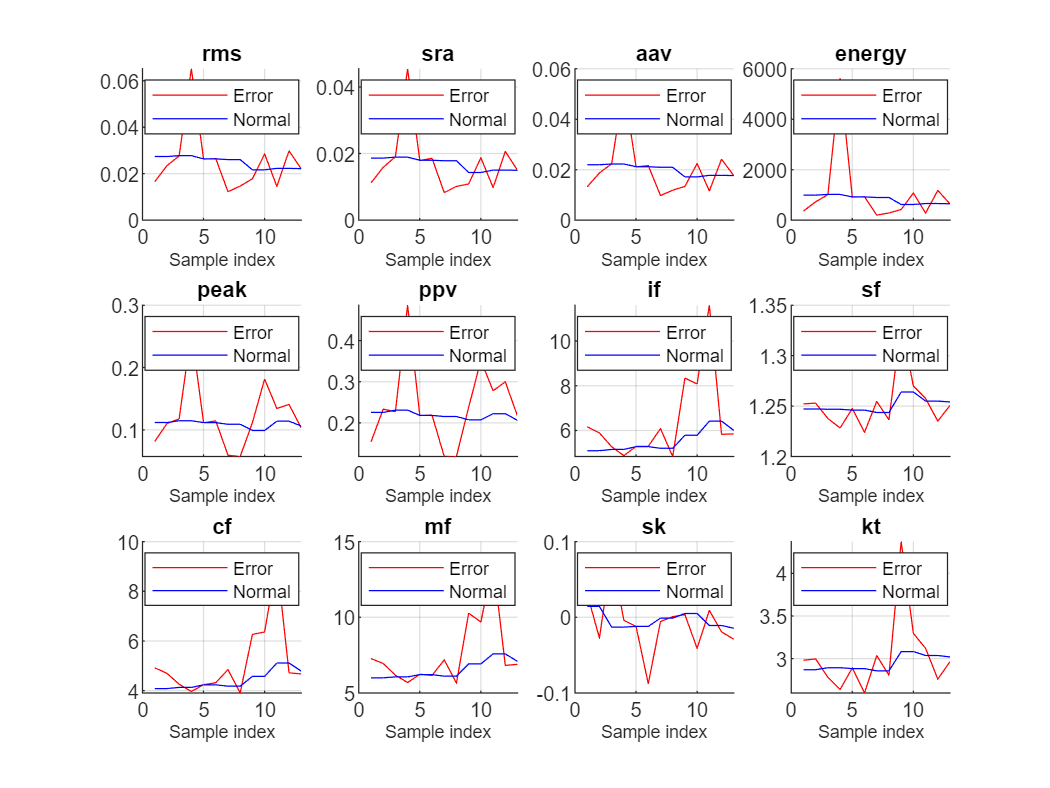

feature_names =["rms" "sra" "aav" "energy" "peak" "ppv" "if" "sf" "cf" "mf" "sk" "kt" "fft"];
figure;
for idx = 1:(length(feature_names)-1)
    avg(idx,1) = get_average_feature(sound_error ,feature_names(idx))       ;
    avg(idx,2) = get_average_feature(sound_normal,feature_names(idx))       ;
    error_features(:,idx)= get_all_feature(sound_error ,feature_names(idx)) ;
    normal_features(:,idx)= get_all_feature(sound_normal,feature_names(idx));
    subplot(3,4,idx); hold on; grid on           ;
    plot(error_features(:,idx),'r-')             ; 
    plot(normal_features(1:13,idx),'b-')         ;
    legend('Error','Normal')                     ;
    legend('Location','best')                    ;
    xlabel('Sample index','FontSize',7)          ;
    title(feature_names(idx),'FontWeight','bold');
end

# Data Preprocessing

# Feature extraction

# Feature Selection/Reduction

# Classification

# Validation

# Fault Monitoring and Warning

# RUL Estimation

# Discussion

# Conclusion

**Functions**

function xfeature = get_features(x)
% This is based on the function timeFeatures() 
% Input: Raw Data (Time-series)
% Output: Struct type
% |
% |---Time features(e.g. RMS, peak2peak, kurtosis)
% |---Frequency features(e.g. FFT, rmsf)
N = length(x);
xfeature.mean=mean(x);
xfeature.std=std(x);

xfeature.rms      =sqrt(sum(x.^2)/N);
xfeature.sra      =(sum(sqrt(abs(x)))/N).^2;
xfeature.aav      =sum(abs(x))/N;
xfeature.energy   =sum(x.^2);
xfeature.peak     =max(x);
xfeature.ppv      =peak2peak(x);
xfeature.if       =xfeature.peak/xfeature.aav;
xfeature.sf       =xfeature.rms/xfeature.aav;
xfeature.cf       =xfeature.peak/xfeature.rms;
xfeature.mf       =xfeature.peak/xfeature.sra;
xfeature.sk       =skewness(x);
xfeature.kt       =kurtosis(x);

p1 = fft(x);
p1(2:end-1)= 2.0 * p1(2:end-1); 
xfeature.fft = p1;
xfeature.rmsf= sqrt(1/N *sum(xfeature.fft.^2));
end

%%
function average_feature = get_average_feature(x,feature_name)
% Input: the whole cell
    FEATURES =3;
    N = length(x);
    feature = 0.0;
    for idx= 1:N
        structure = x{idx,FEATURES};
        val =getfield(structure,feature_name);
        feature = feature + val(1);
    end
    average_feature = feature/N;
end

%%
function vectors = get_all_feature(x,feature_name)
% Input: whole cell
    FEATURES =3;
    N = length(x);
    vectors = [];
    for idx= 1:N
        structure = x{idx,FEATURES};
        val =getfield(structure,feature_name);
        vectors = [vectors; val(1)]; 
    end
end

%%
function [frequency , Amplitude] = get_fft(data,Fs)
% Input : data: Time-series data
%         Fs  : Sampling Frequency
% Output: frequency: Frequency Domain(Bound)
%         Amplitude: Corresponding amplitude of fft data to the frequency
    N = length(data);
    frequency = 0.0:Fs/N:Fs/2;
    fft_data = abs(fft(data)/N);
    fft_data = fft_data(1:floor(N/2)+1);
    fft_data(2:end-1) = 2*fft_data(2:end-1);
    Amplitude = fft_data;
end

%%
function frequency_features = get_freq_features(fft_data, Fs)
% Input  fft_data: fft amplitude data
%        Fs: sampling frequency
% Output frequency_features: table for frequency features. 
    N = length(fft_data);
    frequency_features = table;
    frequency_features.max_amplitude     = max(fft_data);
    frequency_features.frequency_of_max_amplitude = (find(fft_data == max(fft_data))-1)*Fs/N;
    frequency_features.DC_value = fft_data(1);
end
%%



## Reference

[1] (주) KEMP, *Innozinc**세라믹 아연도금**,* [http://kempkorea.com/](http://kempkorea.com/) 

[2] Rauber, Thomas W., Francisco de Assis Boldt, and Flavio Miguel Varejao. "Heterogeneous feature models and feature selection applied to bearing fault diagnosis." *IEEE Transactions on Industrial Electronics* 62.1 (2014): 637-646.

[3] Toliyat, Hamid A., et al. *Electric machines: modeling, condition monitoring, and fault diagnosis*. CRC press, 2017.

[4] 